# ライン検出器とコントローラのROSノード生成

## 初期化

clear; close all; clc; rng('default');

## ライン検出器のGPUコード生成とROSノード化

### コード生成用の関数でテスト

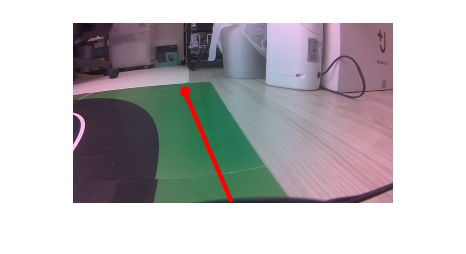

fileName = 'trainVideo_2021_04_08_103802.avi'; % 取得した動画合わせてファイル名を変える
videoReader = vision.VideoFileReader(fileName,'VideoOutputDataType','uint8');
videoPlayer = vision.DeployableVideoPlayer;
while ~isDone(videoReader)
    imdata = videoReader();
    Iocvin = mat2ocv(imdata);
    [predictedPosNorm,Iocvout]= line_detection(Iocvin);
    Iout = ocv2mat(Iocvout);
    videoPlayer(Iout);
end
figure
imshow(Iout);

### CUDAコード生成

cfg = coder.gpuConfig('lib','ecoder',true);
cfg.GenCodeOnly = true;
cfg.TargetLang = 'C++';
cfg.GenerateReport = true;
cfg.ReportPotentialDifferences = false;
cfg.InitFltsAndDblsToZero = false;
cfg.BuildConfiguration = 'Faster Runs';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');

% Only for Jetson targets
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.HardwareImplementation.TargetHWDeviceType = 'ARM Compatible->ARM 64-bit (LP64)';

arg = coder.typeof(uint8(0), [3 1280 720], [0 1 1]);
codegen -config cfg line_detection -args {arg} -report

コードの生成が成功しました:レポートの表示




% Packing the required files to be sent to the target
load(fullfile('codegen','lib','line_detection','buildInfo'));
packNGo(buildInfo,{'packType', 'flat', ...
    'fileName','line_detection'});

### 全てのJetBot上のROSノードを停止

stopJetBotROSNode;

### 生成したCUDAコードをJetBotに転送し、ROSノードとしてビルド

Jetsonに接続するための情報を設定。

% JetsonのIPアドレス、ユーザー名、パスワードを入力
load('jetsonIpAddr');
d = rosdevice(jetsonIpAddr,'jetbot','jetbot');
d.ROSFolder = '/opt/ros/melodic';
d.CatkinWorkspace = '~/workspace/catkin_ws';

必要なファイルを圧縮し、SSH経由で転送

proj = currentProject; rootfolder = proj.RootFolder;
zip('line_detector.zip','line_detector',fullfile(rootfolder,'src','007_hardware_deployment'));
d.putFile('line_detector.zip',d.CatkinWorkspace);
d.system(['rm -fr ',d.CatkinWorkspace,'/src/line_detector']);
d.system(['unzip ',d.CatkinWorkspace,'/line_detector.zip -d ',d.CatkinWorkspace,'/src/']);
d.putFile('line_detection.zip',d.CatkinWorkspace);
d.system(['unzip ',d.CatkinWorkspace,'/line_detection.zip -d ',d.CatkinWorkspace,'/src/line_detector/src/codegen']);
d.system(['touch ',d.CatkinWorkspace,'/src/*/*/*']);

ROSノードをビルド(5分から10分かかる場合があります)

d.system('cd ~/workspace/catkin_ws;source /opt/ros/melodic/setup.bash ;catkin_make');

#### ライン検出ノードの動作確認

Jetson上のライン検出ノードに対してMATLABから画像を入力し、結果を確認する。(/line_detectorが実装したノード)

参考：ライン検出ノードをMATLAB上で実装したときのROSノードグラフ

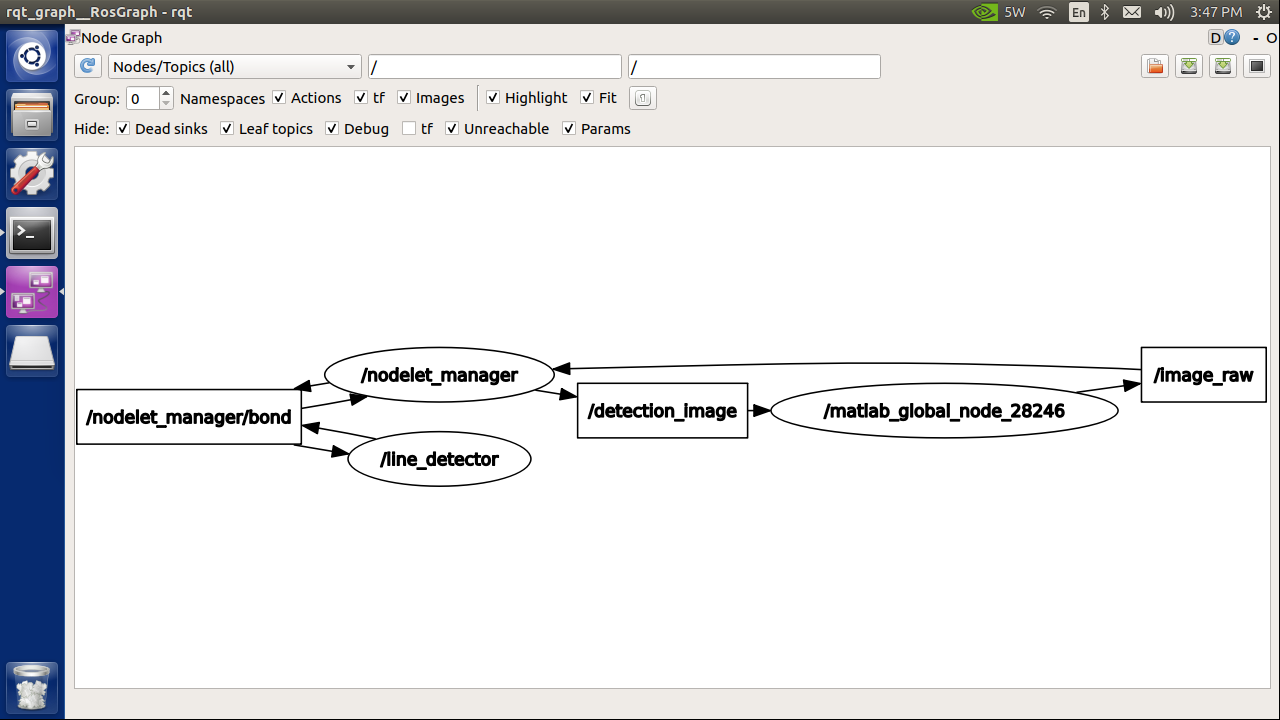

実装した`/line_detector`ノードを起動する

% JetsonのIPアドレス、ユーザー名、パスワードを入力
load('jetsonIpAddr');
d = rosdevice(jetsonIpAddr,'jetbot','jetbot');
d.openShell;

ターミナルが開くので下記のコマンドを入力 (入力した後は閉じないこと)

下記のログの最終行のように"[ INFO] [xxx]: Node started successfully" とターミナルに表示されることを確認。

#### MATLABからJetBotに画像を送信し、ライン検出結果を返す

JetBotに送信する動画ファイルを開く(必要に応じて動画ファイル名を変更する)

fileName = 'trainVideo_2021_04_08_103802.avi';
videoFReader = vision.VideoFileReader(fileName,'VideoOutputDataType','uint8');
rosshutdown;
rosinit(jetsonIpAddr);

NodeURI が http://192.168.1.56:52185/ のグローバル ノード /matlab_global_node_98845 を初期化中


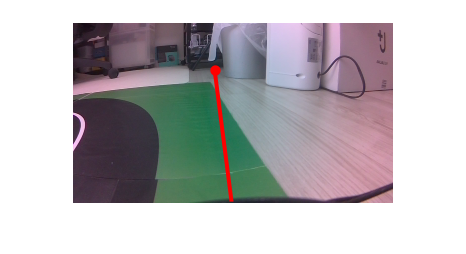

depVideoPlayer = vision.DeployableVideoPlayer;
detImgSub = rossubscriber('/detection_image');
[imgPub,imgMsg] = rospublisher('/image_raw');
imgMsg.Encoding = 'rgb8';
cont = ~isDone(videoFReader);
while cont
    % 動画から画像読み出し
    I = step(videoFReader);

    % 画像トピックとしてROSに発行
    imgMsg.writeImage(I)
    send(imgPub,imgMsg);
    
    % 結果を受信し、表示
    mymsg = receive(detImgSub);
    out = readImage(mymsg);
    step(depVideoPlayer, out);
    cont = ~isDone(videoFReader) && isOpen(depVideoPlayer); % Exit the loop if the video player figure window is closed
end
figure;
imshow(out);

## ライン追従Simulinkモデルの実装

### カメラ画像を入力してライン検出ノードを実行

ターミナルが開いたら下記のコマンドを入力し、カメラとライン検出のノードを実行する

(すでにターミナルが開いている場合は閉じる)

d.openShell;

実行がうまくいくと下記のようがログが表示される

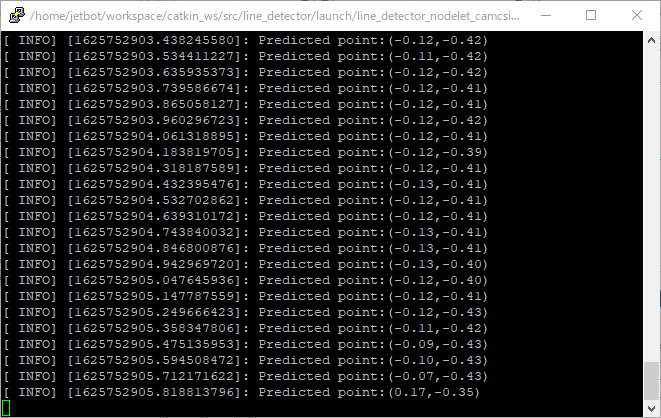

"[ INFO] [1625751896.990854104]: Predicted point:(-0.23,-0.52)" というような表示がターミナルに流れ続ける

(ターミナルは閉じずにそのままにしておく)

### ライン検出結果を確認

rosshutdown;

NodeURI が http://192.168.1.56:52185/ のグローバル ノード /matlab_global_node_98845 をシャットダウン中


rosinit(jetsonIpAddr);

NodeURI が http://192.168.1.56:62182/ のグローバル ノード /matlab_global_node_88430 を初期化中


videoPlayer = vision.DeployableVideoPlayer;
camSub = rossubscriber('/detection_image', @(event,msg) videoPlayer(readImage(msg)));

下記のようなにJetBotのカメラの画像にライン検出結果が赤線で表示されていれば動作している。

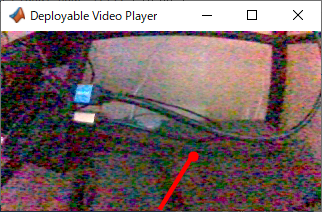

### ライン追従コントローラのSimulinkモデルの動作確認

**注意：下記のようにターミナル上でライン検出のROSノードが動作している状態で実行すること(下記のターミナルは閉じない)**

Simulinkモデルを開く

open_system('ros_line_follower');

1.「シミュレーション」タブの「ROSネットワーク」を選択する

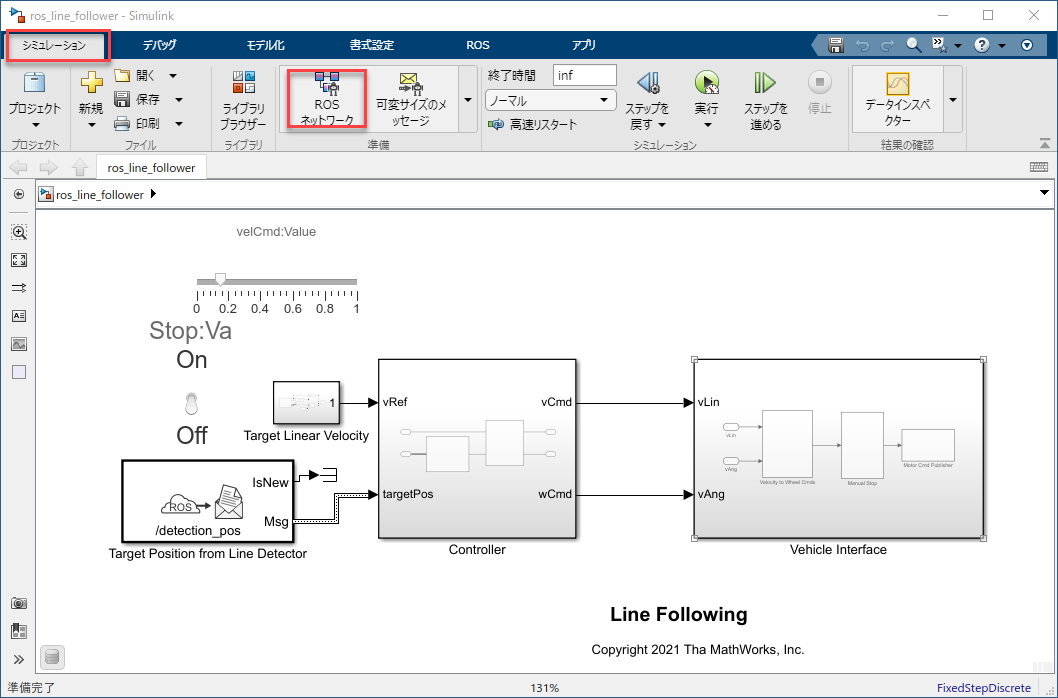

2. 「ネットワークアドレス」を「カスタム」にし、「ホスト名/IPアドレス」にJetBotのIPアドレスを入力し、「OK」をクリックして閉じる

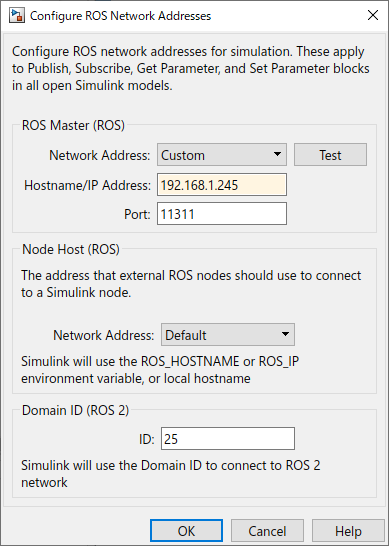

3. 「シミュレーション」タブの実行ボタン(再生マーク)をクリックし、実機と連動実行し、ライン追従できることを確認する。

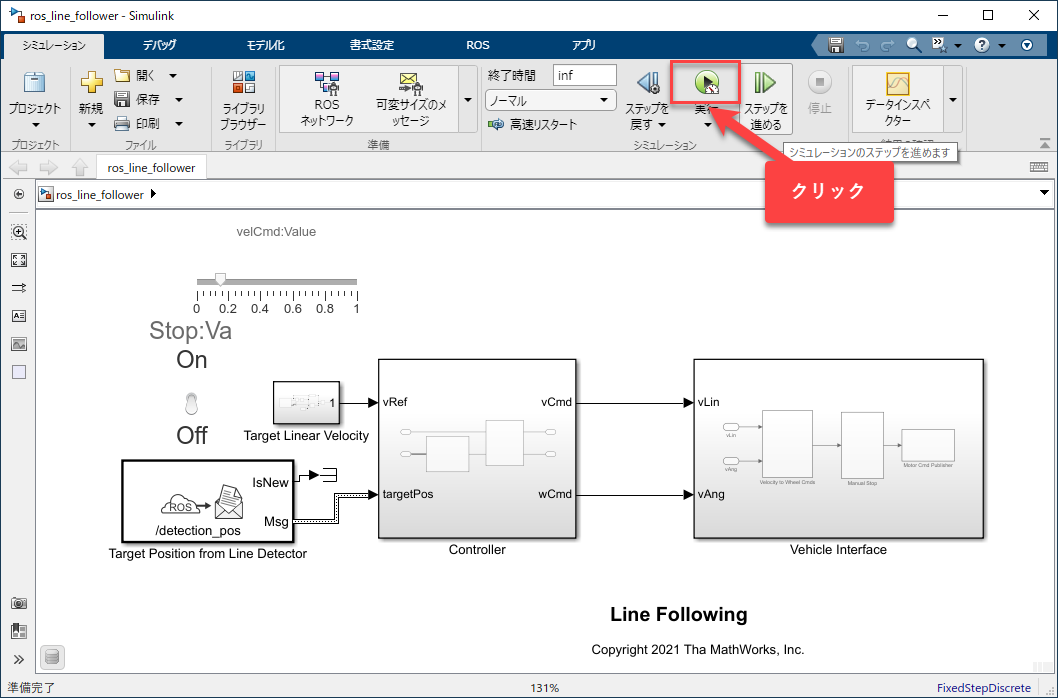

下記のように実行状態になるとタイヤが動き出す(この間もターミナル上でライン検出のメッセージが流れ続けていることを確認)

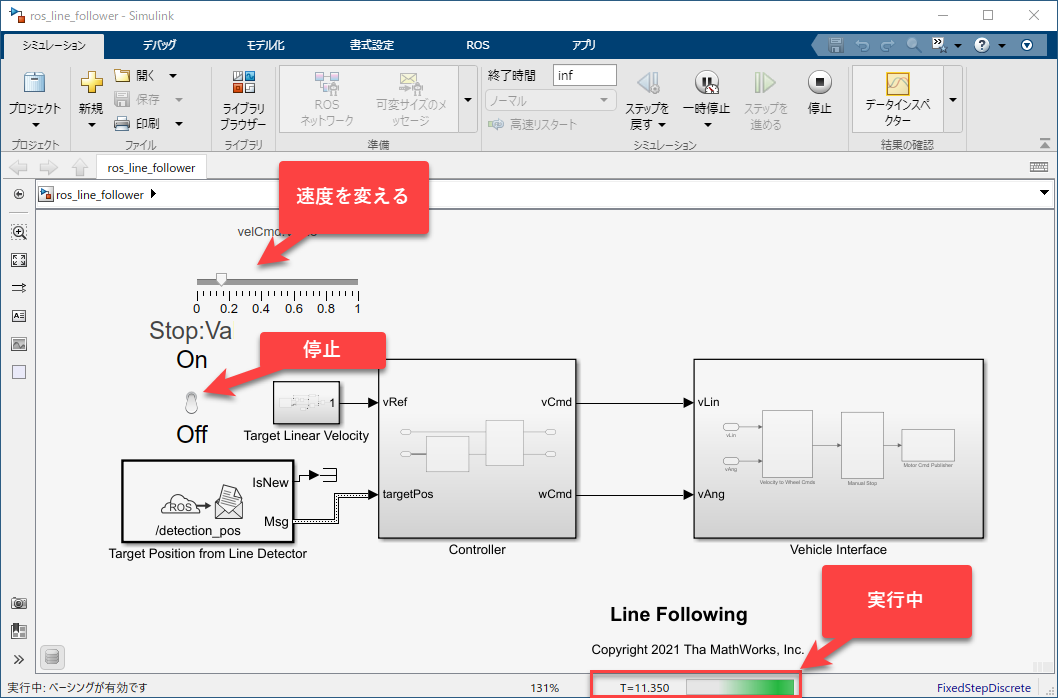

参考：実行時のROSネットワーク(赤い部分がSimulinkモデル)

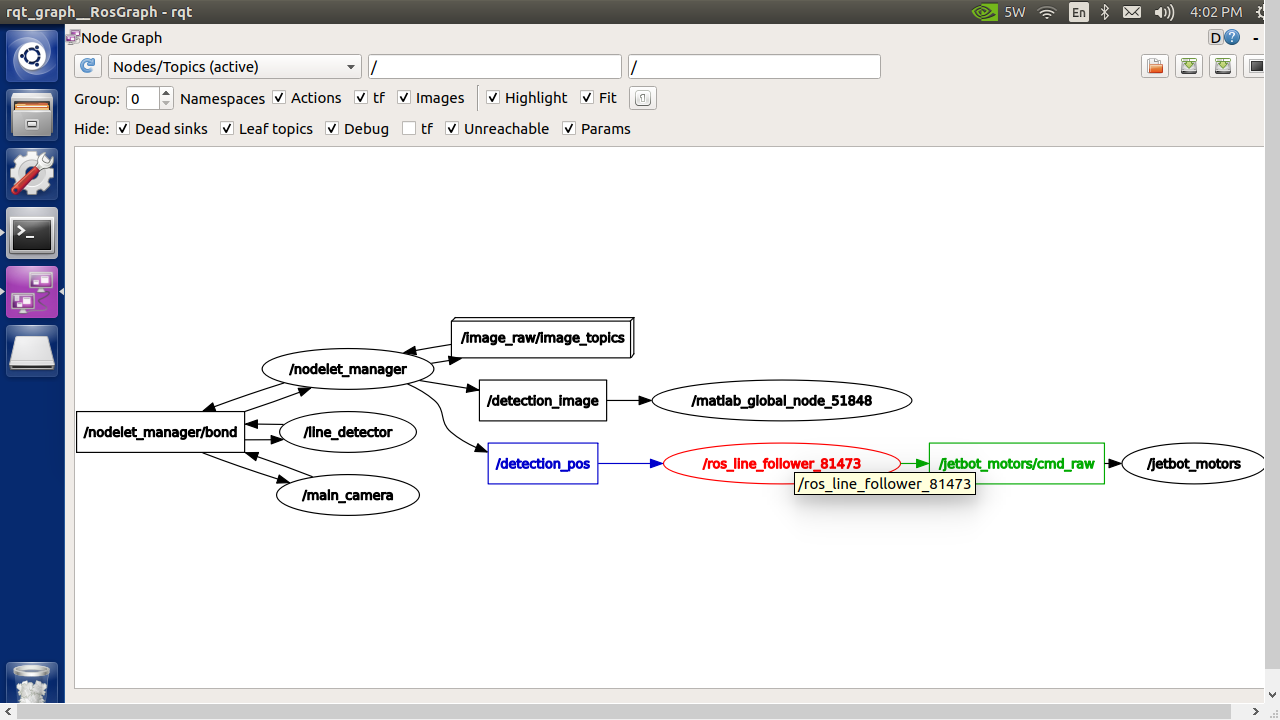

### ROSノード実装

1.「ROS」タブの「Deploy to」の「Manage Remote Device」を選択

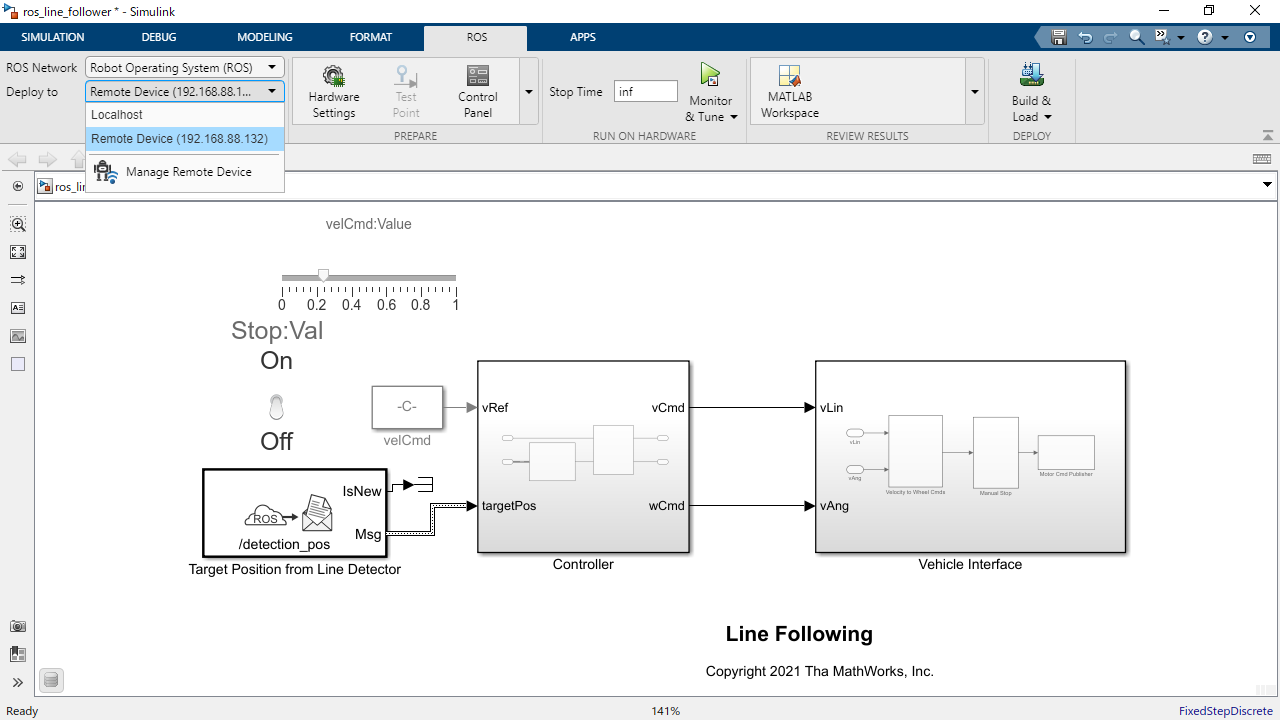

2. JetBotのIPアドレス、ユーザー名、パスワードを設定。さらにcatkin_wsを下記のように設定。

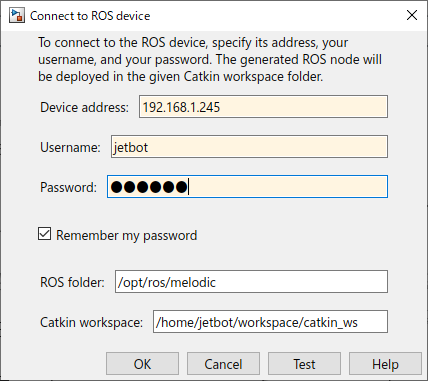

3.JetBot上でroscoreを起動

d.openShell;

4.「ROS」タブの「Build & Load」をクリックし、コード生成とビルド。

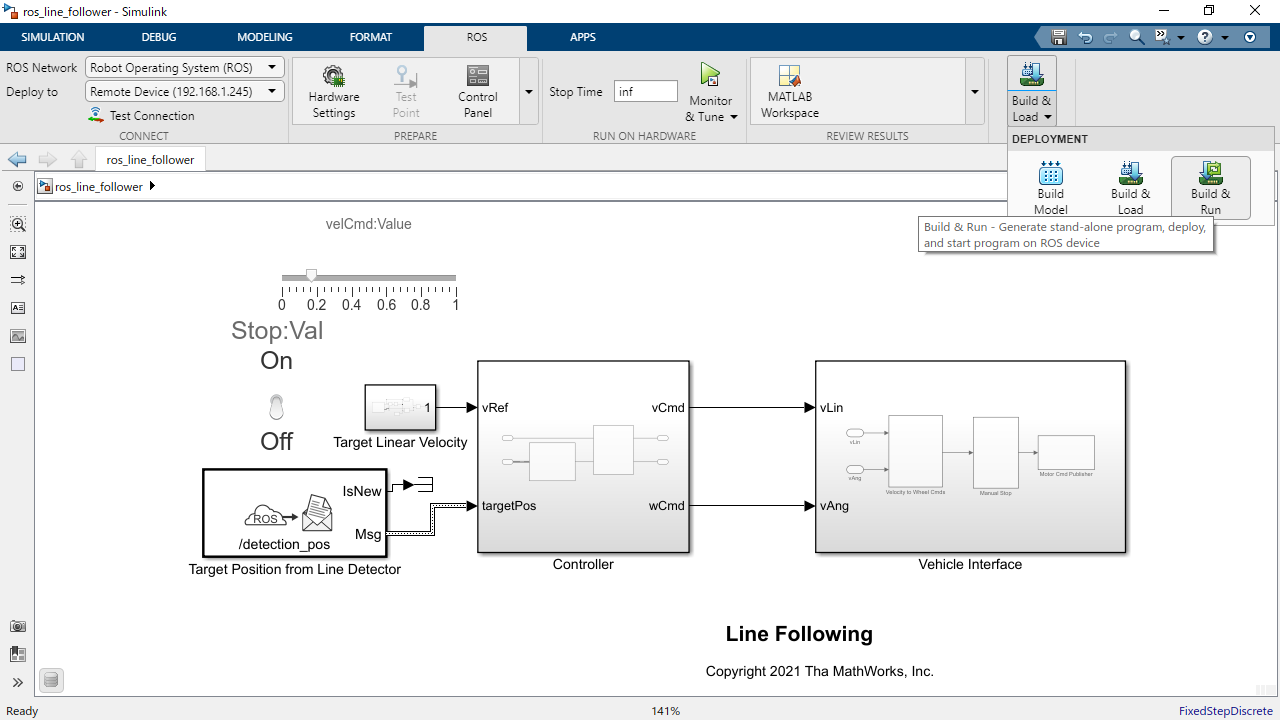

## 全ROSノードをスタンドアローン実行

目標速度と停止指令のみSimulinkから送る

1. 全ROSノードをroslaunchで起動

d.openShell;

2. 速度指令や停止指令を送信するSimulinkモデルを開く

open_system('ros_monitor'); 

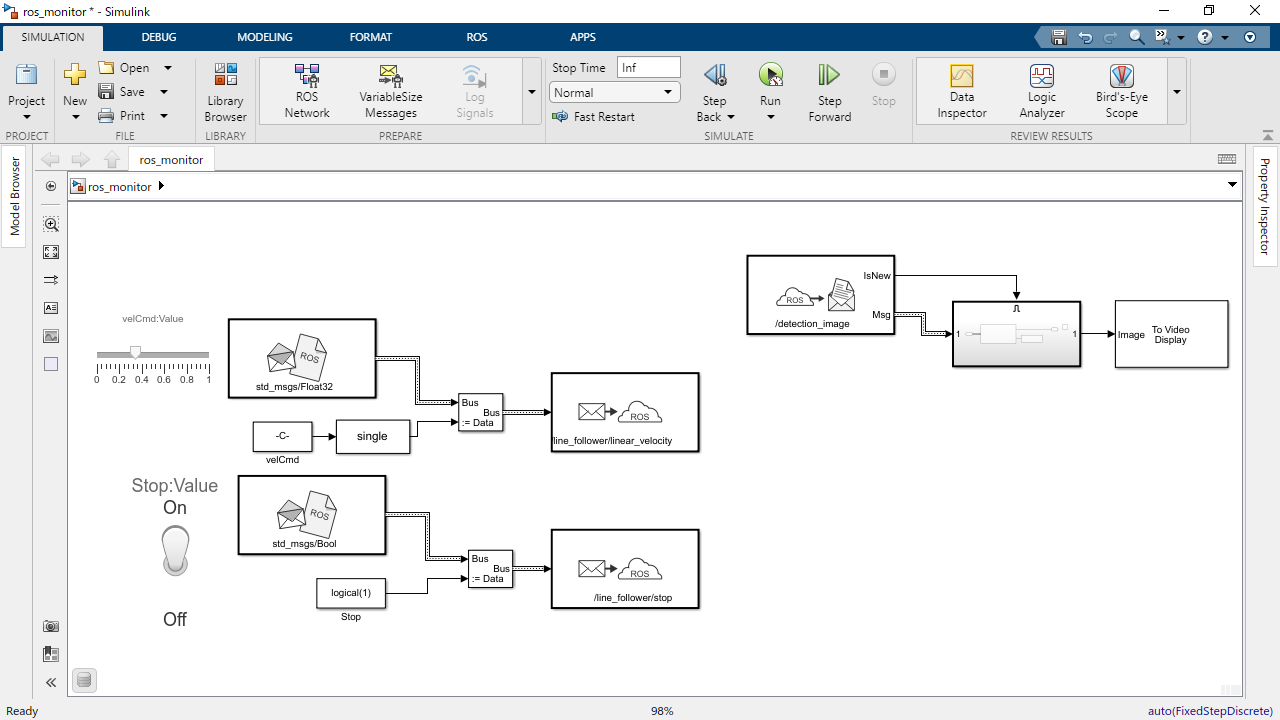

3. モデルを実行し、「Stop」を解除して動作させる

参考：動作させているときのROSノード

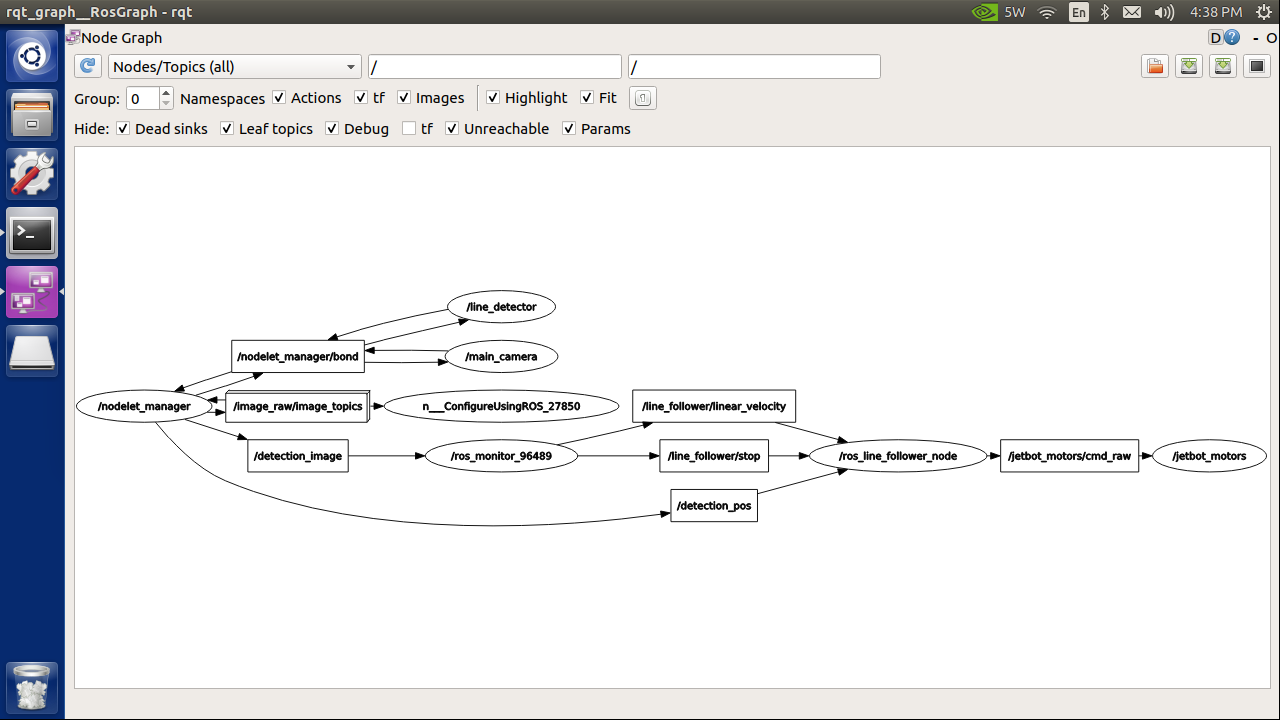

*Copyright 2021 The MathWorks, Inc.*